# L02B_examples

## Example 1

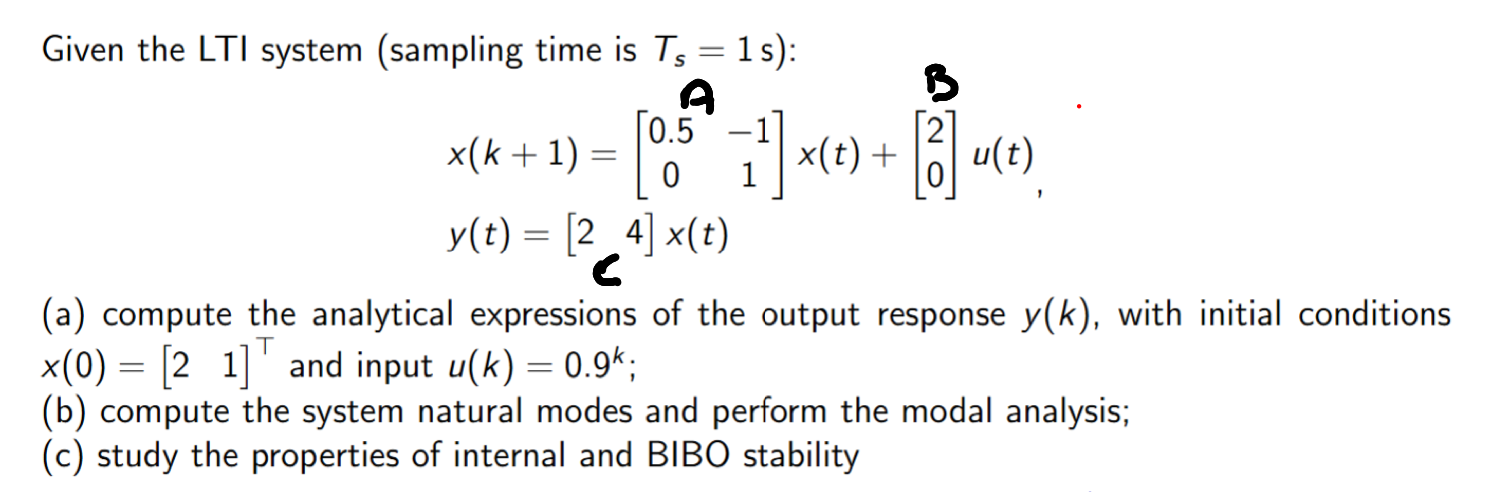

% data

clear
clc

A = [0.5 -1; 0 1];
B = [2;0];
C = [2 4];

x0 = [2;1];
z = tf('z',1);
U = z/(z-0.9);

### Output response

The output response is the sum of zero-state response and zero-input response. In particular, the formula is:

Y(z) = Y_zi(z) + Y_zs(z) = C*z*(z*I-A)^-1*x0 + [C*(z*I-A)^-1*B+D]U(z)

y_zi = C*z*inv(z*eye(size(A,1))-A)*x0;
y_zs = C*inv(z*eye(size(A,1))-A)*B*U;
Y = zpk(minreal(y_zs + y_zi, 1e-2))


Y =
 
    8 z (z-0.4)
  ---------------
  (z-0.9) (z-0.5)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties


% NB I could have done it all in one formula

Let's compute the residues of Y from Partial Fraction Expansion

[num, den] = tfdata(Y(1), 'v'); 
% NB I need 'v' (vectorial form) of num and den because otherwise I can't
% use residuez. If I don't insert 'v' I obtain cell arrays
[r,p,k] = residuez(num,den)

r =    10.0000
   -2.0000


p =     0.9000
    0.5000


k = 0

### Natural modes and modal analysis

lambda = eig(A)

lambda =     0.5000
    1.0000


I obtain 2 eigenvalues:

- l1 = 0.5 -> the corresponding natural mode is 0.5^k -> convergent

- l2 = 1 -> the corresponding natural mode is 1^k (eps(k)) -> bounded

### Stability

#### Internal stability

It is based on eigenvalues' values. In our example, eigs are <= 1, and l2 (=1) has an algebraic multiplicity of 1

=> the system is internally stable

#### Bibo stability

For the bibo stability I have to consider the poles of the tf H(z) = Y(z)/U(z) 

H = zpk(minreal(C*inv(z*eye(size(A,1))-A)*B, 1e-2));


H =
 
     4
  -------
  (z-0.5)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.
Model Properties



zH =

  0×1 empty double column vector



pH = 0.5000

kH = 4.0000

[zH,pH,kH] = zpkdata(H,'v')
% NB I could use tfdata and then residuez as before, but since I need to
% compute just the poles I can use zpkdata

I obtain one pole in 0.5 => the system is bibo stable

## Example 2 

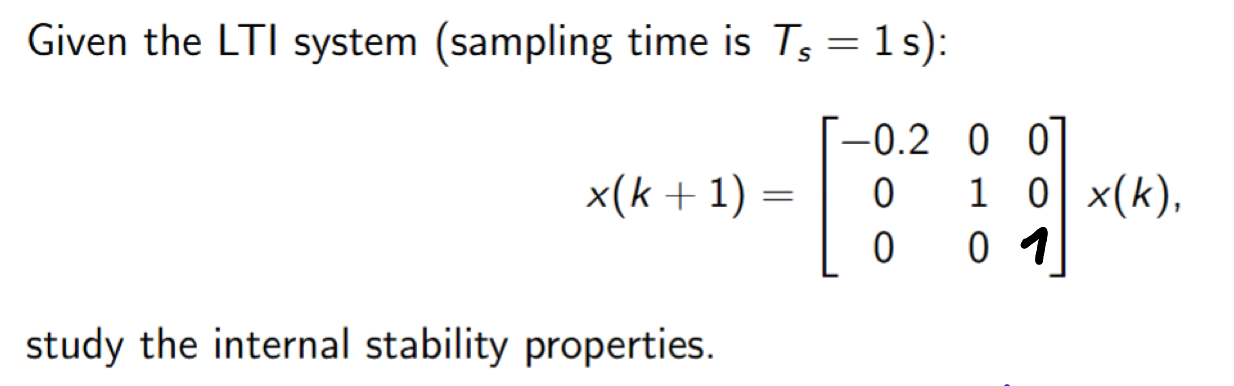

clear 
clc

A = [-0.2 0 0; 0 1 0; 0 0 1];


lambda =    -0.2000
    1.0000
    1.0000


z = tf('z',1);

lambda = eig(A)

I obtain l1 = -0.2 and l2 = 1 with algebraic multiplicity = 2

=> I need to analyse the minimal multiplicity of l

In order to do so, I have to compute

inv(z*eye(size(A,1))-A)


ans =
 
  From input 1 to output...
          1
   1:  -------
       z + 0.2
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
         1
   2:  -----
       z - 1
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
         1
   3:  -----
       z - 1
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


% NB matlab shows the result column by column

% other procedure
roots(minpoly(A)) % e si gode (dovrebbe essere sicura)


I obtain a matrix and now I have to perform the least common multiple (italian mcm) between denominators

I obtain q_a(z) = (z+0.2)*(z-1)

IMPORTANT:

The number of natural modes (associated with an eigenvalue) doesn't depend on the multiplicity of that eigenvalue in the characteristic polynomial p_a(lambda), but it depends on the degree of the monomial (associated with that eigenvalue) in the polynomial q_a(z) !!!!!!!!!!!!!